clear;close all;

## 生成点

warning off

azimuth = 5.135899059569828;
elevation = 1.57897350050879;

r = 1;
x0 = r.*cos(azimuth).*cos(elevation);
y0 = r.*cos(azimuth).*sin(elevation);
z0 = r.*sin(azimuth);
Tao = [x0,y0,z0]

Tao =    -0.0034    0.4109   -0.9117


P3 = [0.698625642652000,1.04004032326448,-0.573794783259771]+Tao;
P4 = [0.710558671267955,-0.419236813348415,-0.777745273229581]-Tao;


num = 8;
laynum = 5;

% 测试 生成 一个截面 测点
Point_out = generate_unit_circle_with_normal_vector2(azimuth,elevation,num,laynum,P3,P4);


## 拟合圆柱

% 测试 测点的拟合
[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Point_out,P3,P4);

## A、B面点测试

testP = Point_out(:,20);
shenglunum = 6;
phi = pi/4;

toff = 0.05;
roff = 0.05;

[PointTable_A,PointTable_B] = Calculat_A_and_B_Points(MTaon',Mcenter',Mradial,Bottom_round_center1',Bottom_round_center2',testP,shenglunum,phi);
[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest(MTaon',Mcenter',Mradial,Bottom_round_center1',Bottom_round_center2',testP,shenglunum,phi,toff,roff);



## 构建复测数据

PointIn = [];
for i = 1:shenglunum
    temp = [PointTable_A_off(:,i),PointTable_A_off(:,end+1-i)];
    PointIn = [PointIn,temp];
end


% 计算点到轴线的投影
Pz1 = Mcenter;
Pz2 = Mcenter+MTaon;

testPoint = zeros(2*shenglunum,3);
for i = 1:2*shenglunum
    temp = PointIn(:,i)';
    [xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(temp,Pz1,Pz2);
    centerPtemp = [xN1,yN1,zN1];
    dirtemp = centerPtemp-temp;
    dirtemp = dirtemp./norm(dirtemp);
    testPoint(i,:) = 0.015*dirtemp + temp;
end
testPoint1 = testPoint';

## 计算距离

Distance = zeros(1,shenglunum);
for i = 1:shenglunum
    shengdao = testPoint1(:,[i,2*shenglunum+1-i]);
    Distance(i) = norm(testPoint1(:,2*i-1)-testPoint1(:,2*i));
end


## 验证

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;
% quiver3(0,0,0,A(1),A(2),A(3))
% quiver3(0,0,0,B(1),B(2),B(3))
% quiver3(0,0,0,C(1),C(2),C(3))
% quiver3(0,0,0,D(1),D(2),D(3))



% scatter3(xN1,yN1,zN1,20,'filled')
scatter3(testP(1),testP(2),testP(3),20,'filled')
% plot3([xN1,testP(1)],[yN1,testP(2)],[zN1,testP(3)])


% scatter3(Tao2(1),Tao2(2),Tao2(3),20,'filled')
% plot3([xN1,Tao2(1)],[yN1,Tao2(2)],[zN1,Tao2(3)])
PointTable_A = PointTable_A';
PointTable_B = PointTable_B';


PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';
scatter3(PointTable_A_off(1,1),PointTable_A_off(1,2),PointTable_A_off(1,3),20,'filled','red')
scatter3(PointTable_A_off(2,1),PointTable_A_off(2,2),PointTable_A_off(2,3),20,'filled','yellow')
scatter3(PointTable_A_off(3,1),PointTable_A_off(3,2),PointTable_A_off(3,3),20,'filled','blue')
scatter3(PointTable_A_off(4,1),PointTable_A_off(4,2),PointTable_A_off(4,3),20,'filled','green')
scatter3(PointTable_A_off(5,1),PointTable_A_off(5,2),PointTable_A_off(5,3),20,'filled','black')

scatter3(PointTable_A_off(6,1),PointTable_A_off(6,2),PointTable_A_off(6,3),20,'filled','red')
scatter3(PointTable_A_off(7,1),PointTable_A_off(7,2),PointTable_A_off(7,3),20,'filled','yellow')
scatter3(PointTable_A_off(8,1),PointTable_A_off(8,2),PointTable_A_off(8,3),20,'filled','blue')
scatter3(PointTable_A_off(9,1),PointTable_A_off(9,2),PointTable_A_off(9,3),20,'filled','green')
scatter3(PointTable_A_off(10,1),PointTable_A_off(10,2),PointTable_A_off(10,3),20,'filled','black')

% scatter3(PointTable_B_off(1,1),PointTable_B_off(1,2),PointTable_B_off(1,3),20,'filled','red')
% scatter3(PointTable_B_off(2,1),PointTable_B_off(2,2),PointTable_B_off(2,3),20,'filled','yellow')
% scatter3(PointTable_B_off(3,1),PointTable_B_off(3,2),PointTable_B_off(3,3),20,'filled','blue')
% scatter3(PointTable_B_off(4,1),PointTable_B_off(4,2),PointTable_B_off(4,3),20,'filled','green')
% scatter3(PointTable_B_off(5,1),PointTable_B_off(5,2),PointTable_B_off(5,3),20,'filled','black')
% 
% scatter3(PointTable_B_off(6,1),PointTable_B_off(6,2),PointTable_B_off(6,3),20,'filled','red')
% scatter3(PointTable_B_off(7,1),PointTable_B_off(7,2),PointTable_B_off(7,3),20,'filled','yellow')
% scatter3(PointTable_B_off(8,1),PointTable_B_off(8,2),PointTable_B_off(8,3),20,'filled','blue')
% scatter3(PointTable_B_off(9,1),PointTable_B_off(9,2),PointTable_B_off(9,3),20,'filled','green')
% scatter3(PointTable_B_off(10,1),PointTable_B_off(10,2),PointTable_B_off(10,3),20,'filled','black')


scatter3(testPoint(1,1),testPoint(1,2),testPoint(1,3),20,'filled','red')
scatter3(testPoint(2,1),testPoint(2,2),testPoint(2,3),20,'filled','yellow')
scatter3(testPoint(3,1),testPoint(3,2),testPoint(3,3),20,'filled','blue')
scatter3(testPoint(4,1),testPoint(4,2),testPoint(4,3),20,'filled','green')
scatter3(testPoint(5,1),testPoint(5,2),testPoint(5,3),20,'filled','black')

scatter3(testPoint(6,1),testPoint(6,2),testPoint(6,3),20,'filled','red')
scatter3(testPoint(7,1),testPoint(7,2),testPoint(7,3),20,'filled','yellow')
scatter3(testPoint(8,1),testPoint(8,2),testPoint(8,3),20,'filled','blue')
scatter3(testPoint(9,1),testPoint(9,2),testPoint(9,3),20,'filled','green')
scatter3(testPoint(10,1),testPoint(10,2),testPoint(10,3),20,'filled','black')

## 计算声道角度

% 计算水平方向向量
theta = zeros(1,shenglunum);
for i = 1:shenglunum
    shengdao1 = testPoint1(:,2*i-1);
    shengdao2 = testPoint1(:,2*i);

    SPXL = shengdao2 - shengdao1;
    theta(i) = acos(dot(MTaon, SPXL') / (norm(MTaon) * norm(SPXL)));  
end

rad2deg(theta)

ans =    44.8956   45.2578   45.7103   45.7103   45.2578   44.8956


## 计算LT

DistanceYC = zeros(1,shenglunum);



for i = 1:shenglunum
    shengdao1 = testPoint1(:,2*i-1);
    shengdao2 = testPoint1(:,2*i);
    Cross_point = YuanZhuJiaoDian(Mcenter,MTaon,Mradial,shengdao1',shengdao2');
    DistanceYC(i) = norm(Cross_point(1,:)- Cross_point(2,:));

end

LTPY = Distance - DistanceYC;


## 相对高度计算



%%%%%%%%%%%%%%%%%%%%%%%%%%%%水平方向计算%%%%%%%%%%%%%%%%%%
% 起始点
A = [0,0,1];
B = MTaon;
C = cross(A,B);
C = C./norm(C);

D = B+tan(phi)*C;
D = D./norm(D);
E = cross(cross(B,C),D);
E = E./norm(E);




% 圆心点
[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(MTaon,Mcenter,Mcenter+MTaon);

% 起始点 （测点半圆的中点）
QiShi = [xN1,yN1,zN1] + E;
QiShi = cross(QiShi,B);




[xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(QiShi,Pz1,Pz2);
zxQS = [xN1,yN1,zN1];

dirQS = QiShi-zxQS;
dirQS = dirQS./norm(dirQS);


alphaA = zeros(1,2*shenglunum);
for i = 1:2*shenglunum
    shengdao = testPoint1(:,i);
    [xN1,yN1,zN1] = foot_of_perpendicular_from_a_point_to_a_line(shengdao,Pz1,Pz2);
    zxP = [xN1,yN1,zN1];
    dirP = shengdao' - zxP;
    dirP = dirP./norm(dirP);
    alphaA(i) = acos(dot(dirP, dirQS) / (norm(dirP) * norm(dirQS)));
end

TiC = sin(alphaA)

TiC =     0.9187    0.9243    0.6564    0.6671    0.2641    0.2778    0.2778    0.2641    0.6671    0.6564    0.9243    0.9187


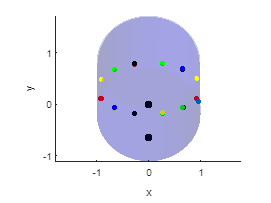


if mod(shenglunum,2)==1 %奇数
    temp6 = floor(shenglunum./2);
    TiC(1:2*temp6) = -TiC(1:2*temp6);
else %偶数
    temp6 = shenglunum./2;
     TiC(1:2*temp6) = -TiC(1:2*temp6);
end




DegAlpha = rad2deg(alphaA);
DegAlpha(DegAlpha>90) = 180 - DegAlpha(DegAlpha>90);
% DegAlpha = DegAlpha-2.5

scatter3(QiShi(1),QiShi(2),QiShi(3),40,'filled','black')
scatter3(Mcenter(1),Mcenter(2),Mcenter(3),40,'filled','black')

## 计算权重

k1 = 0.5;
k2 = 0.6;
k3 = 0;
k4 = 0.15;

gk1 = [1.570796,0.392699,0.19635,0.122718,0.085903];
gk2 = [1.513365,0.360325,0.174351,0.106311,0.072959];
gk3 = [2,2/3,2/5,2/7,2/9];
gk4 = [1.838286,0.556753,0.315143,0.215852,0.162469];

gk = gk1;
k = k1;


TiYiCe = TiC(1:2:2*shenglunum);


if mod(shenglunum,2)==1 %奇数
    temp6 = floor(shenglunum./2);
    TiYiCe(temp6+1) = 0;
end

t_k = zeros(shenglunum-1,1);
w = zeros(shenglunum,1);
f = zeros(shenglunum,1);

    for i=1:shenglunum  
        count_tk = 1;
        for m=1:shenglunum
            if(m~=i)
            t_k(count_tk) =  TiYiCe(m);
            count_tk = count_tk + 1;
            end
        end  

        for j=1:(shenglunum+1)/2
             f(j) = -sum(prod(nchoosek(t_k,(shenglunum+1-2*j)),2)); 
             w(i) = w(i) + gk(j)*f(j);
        end

        mul = 1;
        for m=1:shenglunum
            if(m ~= i)
                mul = mul*(TiYiCe(i) - TiYiCe(m));
            end
        end
        w(i)=w(i)/((1-TiYiCe(i)*TiYiCe(i))^k * mul);    
    end

    Wquanzhong = abs(repelem(w,2))

Wquanzhong =     0.1886
    0.1886
    0.3054
    0.3054
    0.5054
    0.5054
    0.5051
    0.5051
    0.2998
    0.2998
